s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gp = 1/(s^2+ 4*s +3)

Gp =
 
        1
  -------------
  s^2 + 4 s + 3
 
Continuous-time transfer function.
Model Properties


zpk(Gp)

ans =
 
       1
  -----------
  (s+3) (s+1)
 
Continuous-time zero/pole/gain model.
Model Properties


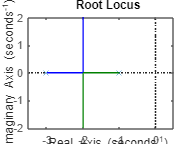

rlocus(Gp)


T = 0.01;

K = 3;
z = 1.8749;

Gc = K * (s + z)/s ;

zpk(Gc)

ans =
 
  3 (s+1.875)
  -----------
       s
 
Continuous-time zero/pole/gain model.
Model Properties


FT_cl = feedback(Gp * Gc, 1)

FT_cl =
 
         3 s + 5.625
  -------------------------
  s^3 + 4 s^2 + 6 s + 5.625
 
Continuous-time transfer function.
Model Properties


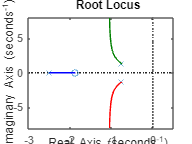

rlocus(FT_cl)

FT_cl_zpk = zpk(FT_cl)

FT_cl_zpk =
 
          3 (s+1.875)
  ---------------------------
  (s+2.5) (s^2 + 1.5s + 2.25)
 
Continuous-time zero/pole/gain model.
Model Properties


pole(FT_cl_zpk)

ans =   -2.4999 + 0.0000i
  -0.7500 + 1.2990i
  -0.7500 - 1.2990i


zero(FT_cl_zpk)

ans = -1.8749

#### 4.Resposta ao degrau

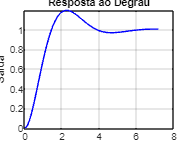

[y_cl, tOut_cl] = step(FT_cl);
plot(tOut_cl, y_cl, 'Color', 'blue');
xlabel('Tempo (s)');
ylabel('Saída');
title('Resposta ao Degrau');
grid on;


% Obtém informações da resposta ao degrau
info = stepinfo(y_cl, tOut_cl);

% Tempo de acomodação a 2%
tempo_acomodacao = info.SettlingTime;

% Ultrapassagem percentual
ultrapassagem = info.Overshoot;

% Exibe os resultados no console
fprintf('Tempo de acomodação a 2%%: %.4f s\n', tempo_acomodacao);

Tempo de acomodação a 2%: 5.5647 s


fprintf('Ultrapassagem percentual: %.2f%%\n', ultrapassagem);

Ultrapassagem percentual: 18.89%


Digital

Gcz = c2d(Gc, T, 'tustin');
Gcz_zpk = zpk(Gcz)

Gcz_zpk =
 
  3.0281 (z-0.9814)
  -----------------
        (z-1)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.
Model Properties



Gpz = c2d(Gp, T, 'zoh');
Gpz_zpk = zpk(Gpz)

Gpz_zpk =
 
  4.9339e-05 (z+0.9868)
  ---------------------
   (z-0.99) (z-0.9704)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.
Model Properties



Tz = feedback(Gcz *  Gpz, 1);  
Tz_zpk = zpk(Tz)

Tz_zpk =
 
   0.0001494 (z+0.9868) (z-0.9814)
  ----------------------------------
  (z-0.9754) (z^2 - 1.985z + 0.9852)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.
Model Properties


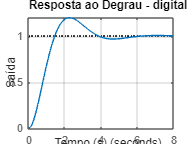


step(Tz)
title('Resposta ao Degrau - digital')
xlabel('Tempo (s)')
ylabel('Saída')
grid on


[y, t] = step(Tz);
ess = 1 - y(end);  % Erro em regime permanente
fprintf('Erro em regime permanente: %.6f\n', ess);

Erro em regime permanente: -0.002701
